%this script fits all the histograms in either 1 or two gaussians. 

addpath('C:\Users\User\Desktop\GMM\functions_folder');
addpath('C:\Users\User\Desktop\GMM\EM_GMM_demo_folder\demo_functions');
file_path = "C:/Users/User/Desktop/uzh_intern/alrisDistortionFit/PBCO/PBCO_1_3_inplane/P2/results/";
hist_path = "20250921_090401_iters2000_epochs500_lr0.004" ;
hist_path2 = "/histogram_matrix.mat"

hist_path2 = "/histogram_matrix.mat"

total_path = file_path + hist_path + hist_path2;

file = load(total_path);

base_path = "C:/Users/User/Desktop/uzh_intern/alrisDistortionFit/PBCO/PBCO_1_3_inplane/P2";
max_amp_name = "/PBCO_1_3_P2_max_bound_vectors.txt";
path_max_mode_amps = base_path + max_amp_name;

displacive_mode_names = "/matlab_displacive_modes.mat";
path_displacive_modes = base_path + displacive_mode_names;

max_mode_amps = load(path_max_mode_amps);
displacive_modes_struct = load(path_displacive_modes);

displacive_modes = displacive_modes_struct.displacive_modes;
%indices_to_zero = [2 , 5 , 6 , 10 , 11 , 13 , 14 , 18 , 22 , 23 , 38 , 43]
indices_to_zero = [2 , 5 , 6 , 10 , 11 ,12,  13 , 14 , 18 , 19 ,22 , 23 , 38 , 43 , 4 , 17 , 19 , 46];
for index = 1:length(indices_to_zero)
    this_max_mode_to_remove = indices_to_zero(index);
    max_mode_amps(this_max_mode_to_remove) = 0.0;
end


total_mode_num = 52;
nbins = 100;
means = zeros([total_mode_num,1]);
fitting_resnorm = zeros([total_mode_num,1]);

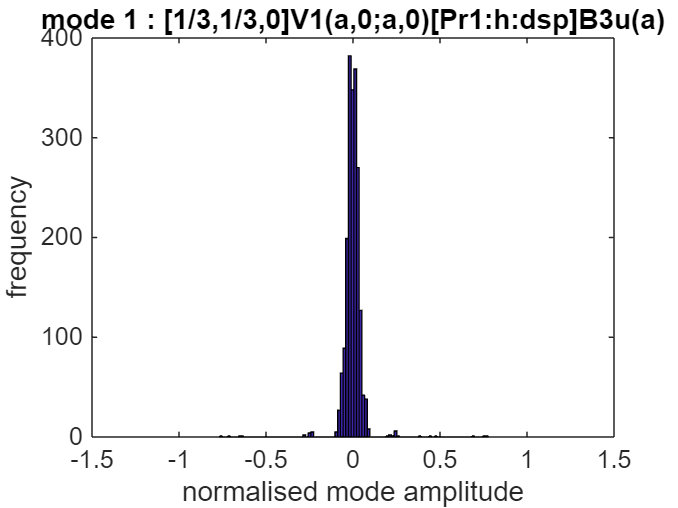

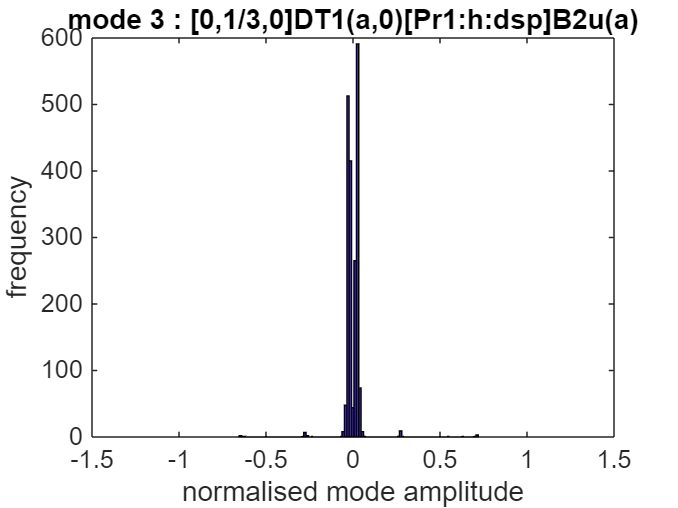

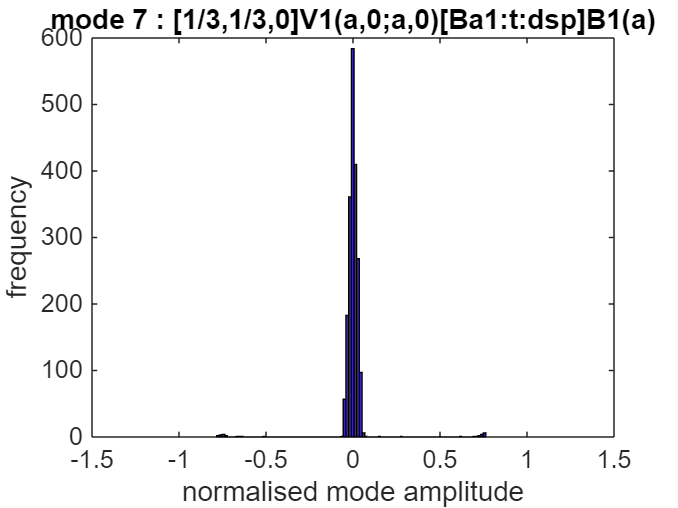

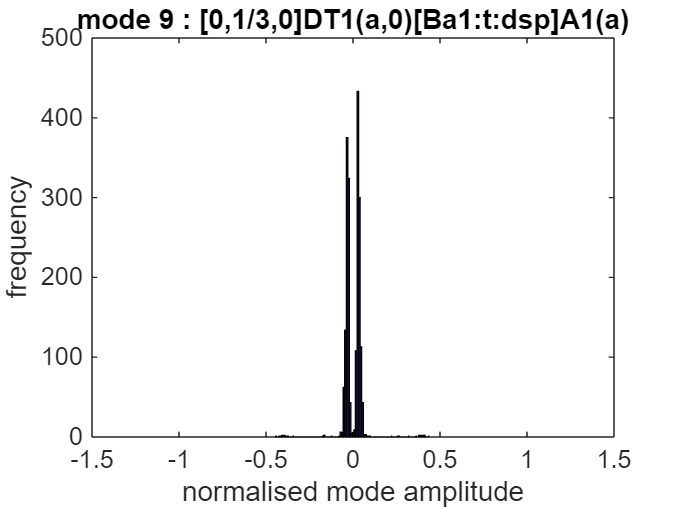

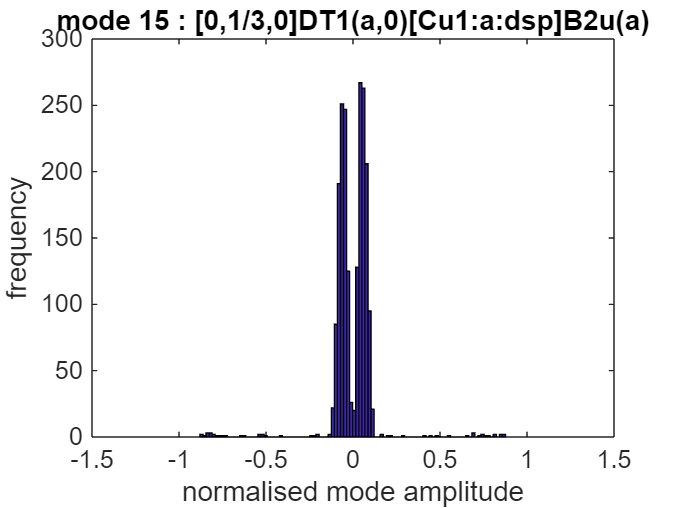

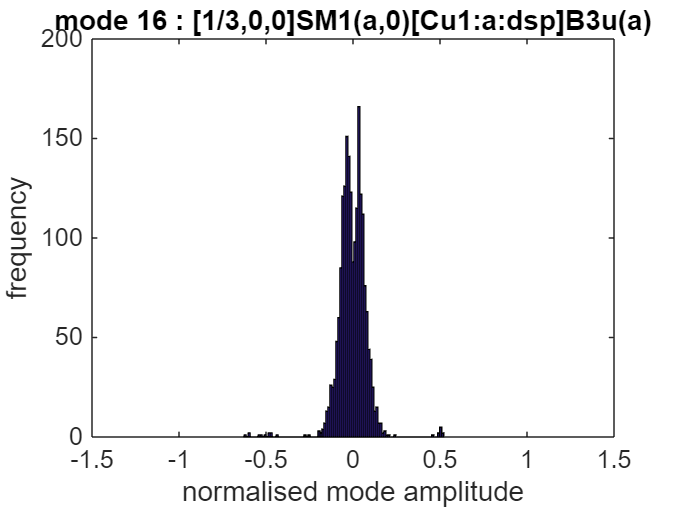

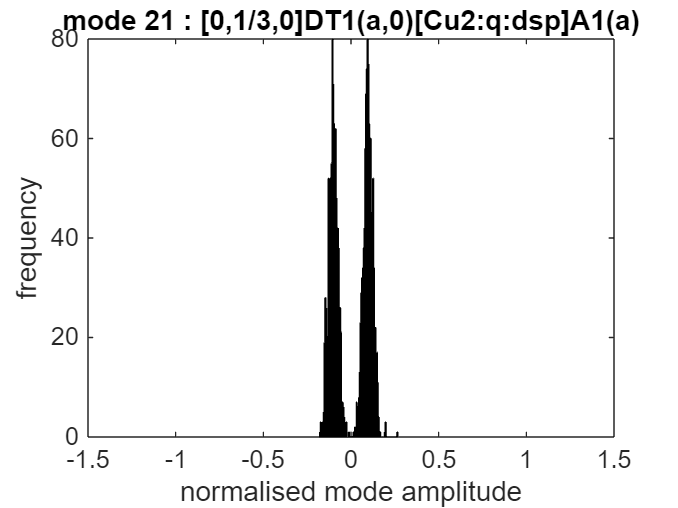

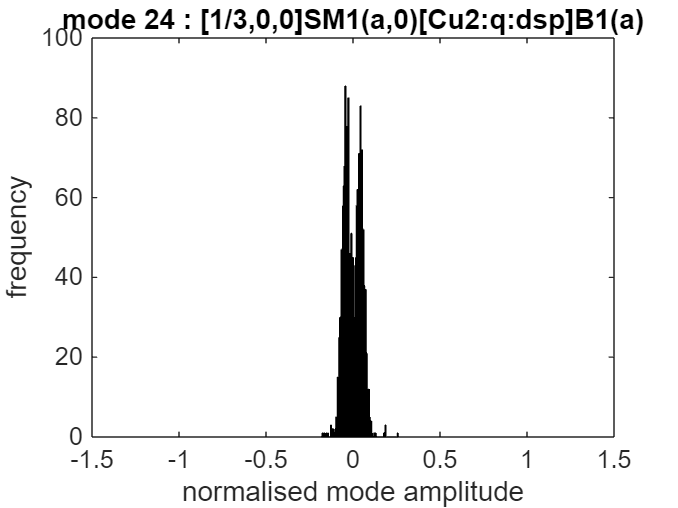

% means = load('means.csv');
% fitting_resnorm = load('fitting_resnorm.csv');

for iter = 1: total_mode_num
    %if fitting_resnorm(iter) >= 5e-3
    if max_mode_amps(iter) > 0
        EN = max_mode_amps(iter);
        en = linspace(-EN , EN , nbins);
        SPC = file.histogram_matrix(:, iter) / max_mode_amps(iter);
        spc = histcounts(SPC , nbins , "BinLimits",[-1 , 1]);

       HIST_fig = figure;
        hist(SPC , nbins);
        xlim([-1.5 , 1.5]);
        xlabel('normalised mode amplitude');
        ylabel('frequency');
        title(sprintf("mode %d : %s" , iter , char(displacive_modes(iter))));
       hold off
       pic_folder_path = 'C:\Users\User\Desktop\uzh_intern\alrisDistortionFit\PBCO\PBCO_1_3_inplane\P2\histogram_pngs_run3\';
       pic_name = num2str(iter);

       saveas(HIST_fig ,[pic_folder_path pic_name '.png']);

        % cluster_number = 1;
        % [gmm_output_structure, gmm_object] = function_gmm_unshared(en, SPC, cluster_number, spc, -EN, EN);
        % 
        % if gmm_output_structure.resnorm <= 5e-3
        %     fitting_resnorm(iter) = gmm_output_structure.resnorm;
        %     means(iter) = gmm_output_structure.optimfit_params(2);
        % else
        %     fitting_resnorm(iter) = 10000;
        %     means(iter) = 10000;
        % end
    else
        fitting_resnorm(iter) = 0;
        means(iter) = 0;
    end
end


means_path = "/means.csv";
resnorm_path = "/fitting_resnorm.csv";

means_path = file_path + hist_path + means_path;
resnorm_path = file_path + hist_path + resnorm_path;
writematrix(means , 'C:/Users/User/Desktop/uzh_intern/alrisDistortionFit/PBCO/results/20250812_231021_iters7000_epochs75_lr0.1/means.csv');
writematrix(fitting_resnorm, 'C:/Users/User/Desktop/uzh_intern/alrisDistortionFit/PBCO/results/20250812_231021_iters7000_epochs75_lr0.1/fitting_resnorm.csv');




% means = load('C:/Users/User/Desktop/uzh_intern/alrisDistortionFit/PBCO/results/20250812_231021_iters7000_epochs75_lr0.1/means.csv');
% fitting_resnorm = load('C:/Users/User/Desktop/uzh_intern/alrisDistortionFit/PBCO/results/20250812_231021_iters7000_epochs75_lr0.1/fitting_resnorm.csv');

total_mode_num = 1290;
ii = 1;
for i = 1: total_mode_num
    if means(i) >= 5e-5

        idx_list(ii) = i - 1;
        ii = ii + 1;
    end
end

ii = 1;
for i = 1: total_mode_num
    if means(i) < 5e-5

        exc_idx_list(ii) = i - 1;
        ii = ii + 1;
    end
end

strain_modes = [111, 411, 711, 906, 1101];
exc_idx_list1 = setdiff(exc_idx_list , strain_modes);


writematrix(idx_list, 'C:/Users/User/Desktop/uzh_intern/alrisDistortionFit/PBCO/results/20250812_231021_iters7000_epochs75_lr0.1/remove_idx_list.txt');
writematrix(exc_idx_list1 ,'C:/Users/User/Desktop/uzh_intern/alrisDistortionFit/PBCO/results/20250812_231021_iters7000_epochs75_lr0.1/exc_idx_list.csv');